## Acinetobacter Data

From Magenta supplementary dataset

testFile = 'acinetobacter.xlsx';
trainingData = 'orig_ecoli.xlsx';
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;

summaryTable = 1×12 table
      min       median       max      range       mean        std      interactionCount    synergyCount    antagonismCount    orthologsCount    rejectNormality    pNormality
    _______    ________    _______    ______    ________    _______    ________________    ____________    _______________    ______________    _______________    __________

    -2.2746    -0.23072    0.61829    2.8929    -0.29397    0.61135           45                23               12                1633              false          0.15091  


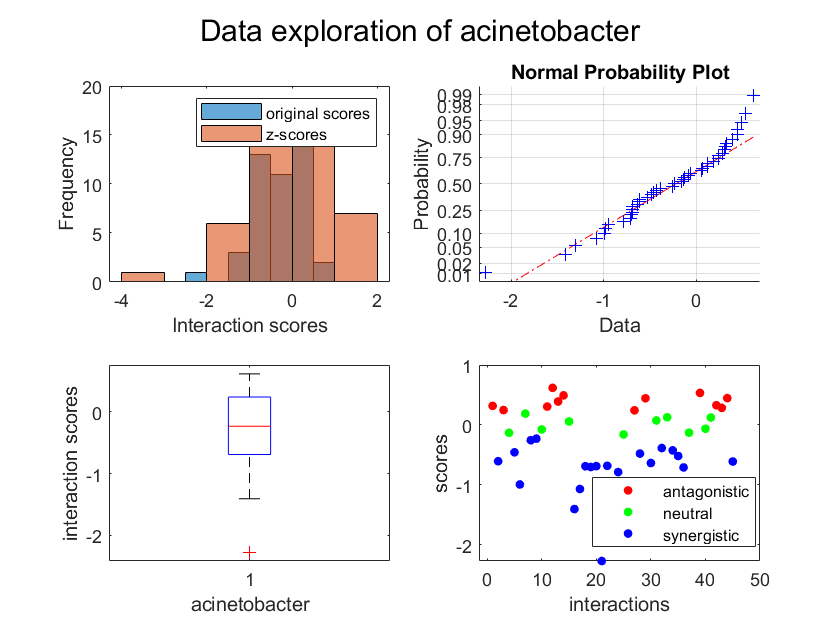

[summary,drugList] = dataExplore(testFile);

compareFiles = [{testFile};{'orig_ecoli.xlsx'}];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    acinetobacter score    orig_ecoli score
    ______    ______    ___________________    ________________

    "AMK"     "NAL"           0.24682               0.7145     
    "AMK"     "RIF"          -0.13242               1.0995     
    "AMK"     "TET"          -0.45847               0.7785     
    "NAL"     "RIF"           0.38991                0.437     
    "NAL"     "TET"           0.49292                3.158     
    "RIF"     "TET"          0.056965               -0.252     
    "AMK"     "NAL"          -0.69083               0.7145     
    "AMK"     "RIF"          -0.70375               1.0995     


interactionCounts = 2×2 table
                     acinetobacter    orig_ecoli
                     _____________    __________

    acinetobacter          0              18    
    orig_ecoli             0               0    


R_values = 2×2 table
                     acinetobacter    orig_ecoli
                     _____________    __________

    acinetobacter          0            0.3041  
    orig_ecoli             0                 0  


P_values = 2×2 table
                     acinetobacter    orig_ecoli
                     _____________    __________

    acinetobacter          0           0.21987  
    orig_ecoli             0                 0  


orthologCounts = 2×2 table
                     acinetobacter    orig_ecoli
                     _____________    __________

    acinetobacter          0              0     
    orig_ecoli             0              0     


indigoSummary = indigoRun(testFile,trainingData,valMethod,K, standardize,input_type);

Run 1
Elapsed time is 13.837196 seconds.
Run 2
Elapsed time is 13.796481 seconds.
Run 3
Elapsed time is 19.710231 seconds.
Run 4
Elapsed time is 17.099343 seconds.
Run 5
Elapsed time is 13.931722 seconds.


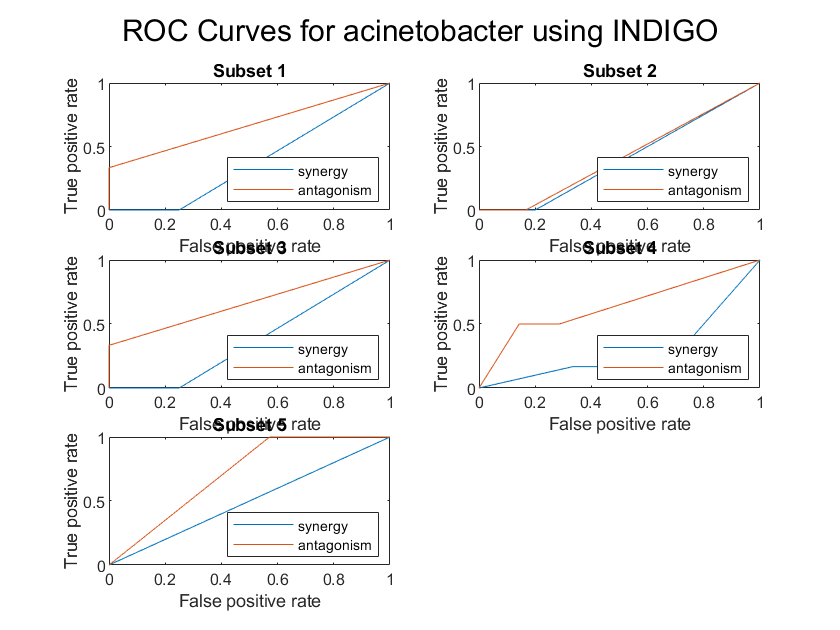

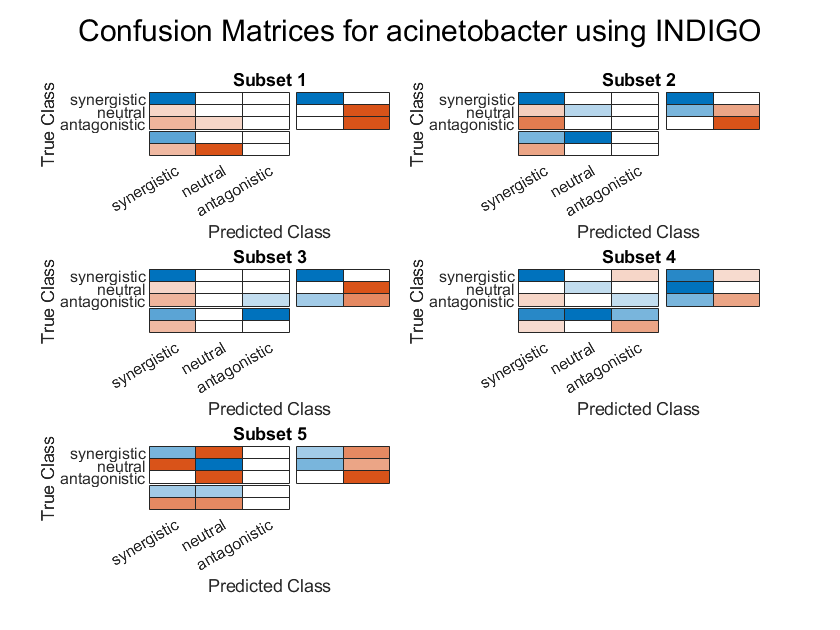

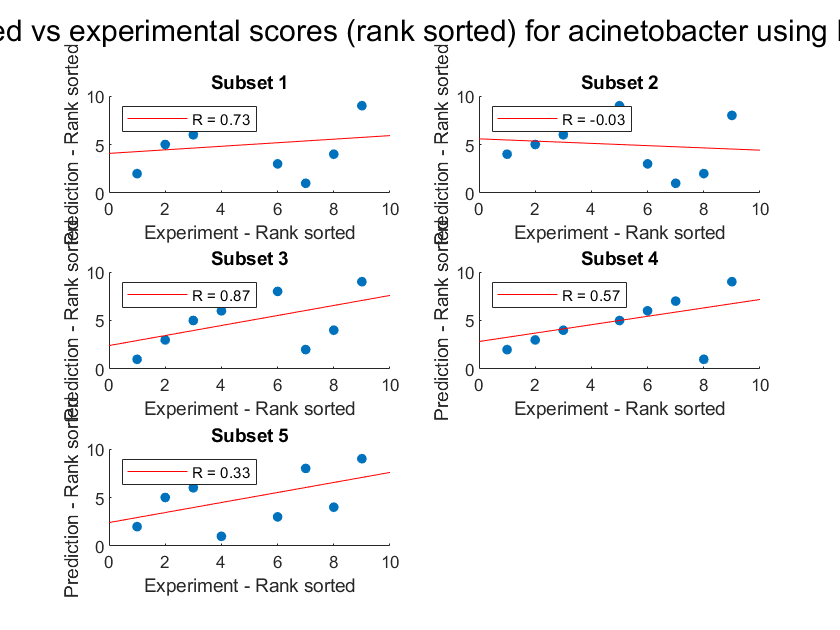

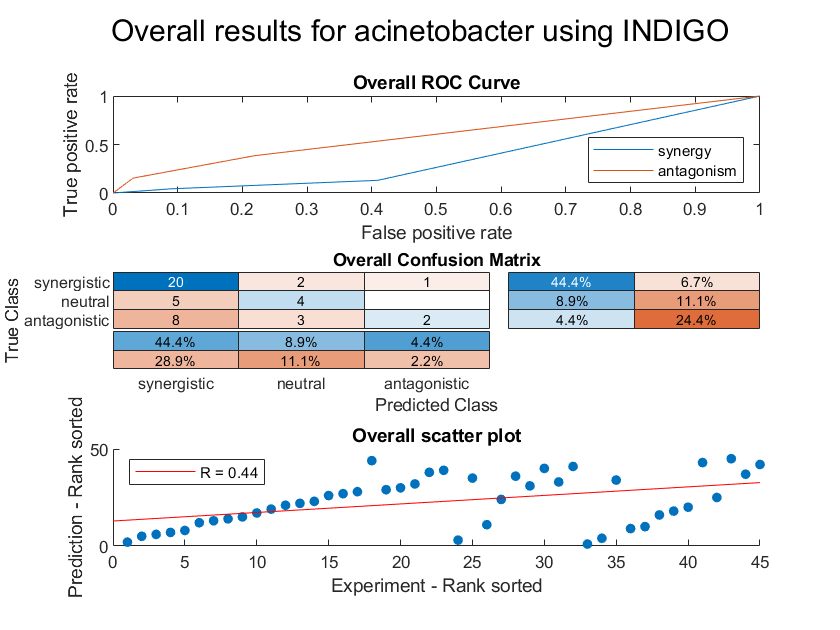

resultsTable = 5×12 table
                Interactions    R (rank)      P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    _________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9            0.7289

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.49279
    P value                     0.29817
    Accuracy                    0.57778
    Absolute error              0.62222
    Precision (synergy)         0.58333
    Recall (synergy)            0.83333
    Precision (antagonism)          NaN
    Recall (antagonism)         0.16667
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.38556
    AUC - ROC (antagonism)      0.62143


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       45
    R (rank)                      0.43708
    P value                     0.0026813
    Accuracy                      0.57778
    Absolute error                0.62222
    Precision (synergy)           0.60606
    Recall (synergy)              0.86957
    Precision (antagonism)        0.66667
    Recall (antagonism)           0.15385
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.36364
    AUC - ROC (antagonism)        0.59375


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'acinetobacter.xlsx';
trainingData = 'orig_ecoli.xlsx';
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 14.973729 seconds.
Run 2
Elapsed time is 15.344241 seconds.
Run 3
Elapsed time is 29.504877 seconds.
Run 4
Elapsed time is 19.638345 seconds.
Run 5
Elapsed time is 17.903812 seconds.


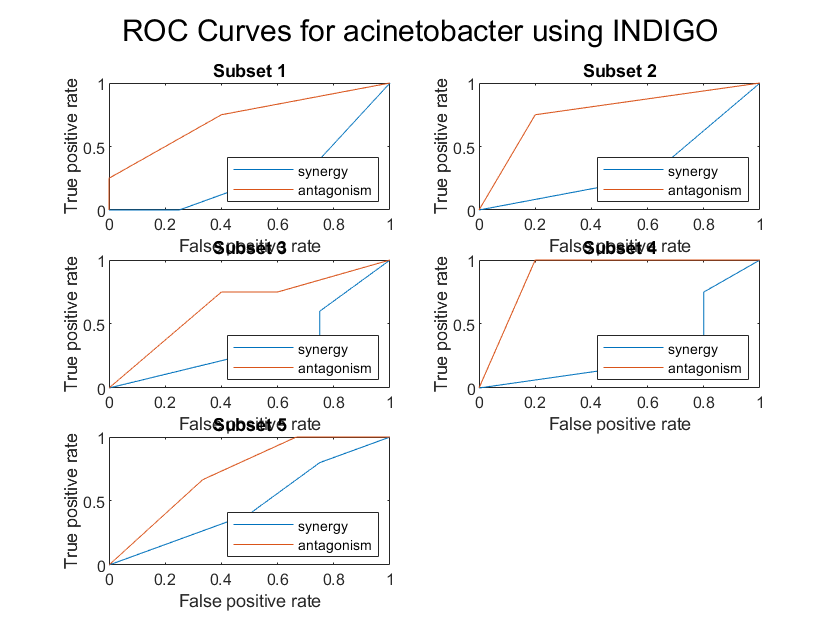

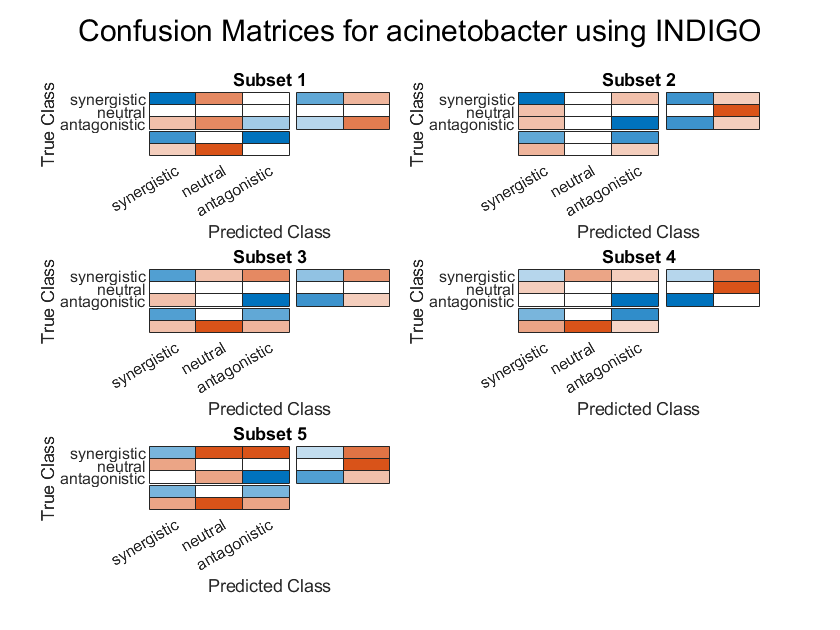

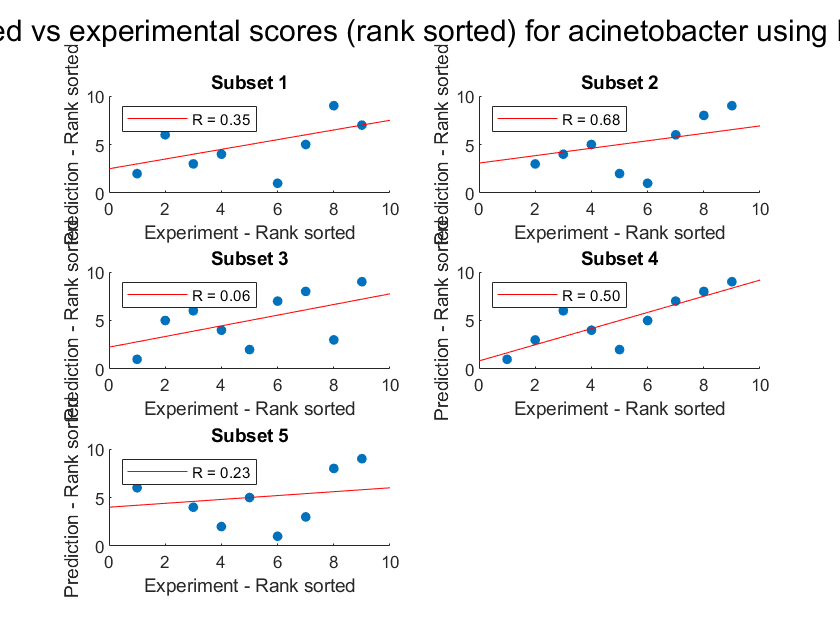

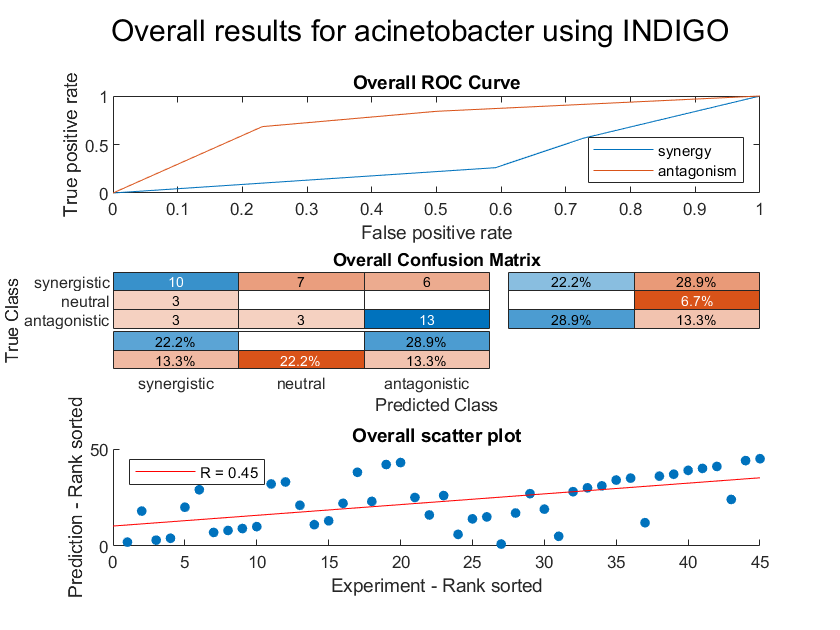

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9           0.34602    

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.36194
    P value                     0.40472
    Accuracy                    0.51111
    Absolute error              0.68889
    Precision (synergy)         0.60333
    Recall (synergy)               0.44
    Precision (antagonism)         0.73
    Recall (antagonism)         0.68333
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)            0.34
    AUC - ROC (antagonism)      0.75444


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       45
    R (rank)                      0.44573
    P value                     0.0021512
    Accuracy                      0.51111
    Absolute error                0.68889
    Precision (synergy)             0.625
    Recall (synergy)              0.43478
    Precision (antagonism)        0.68421
    Recall (antagonism)           0.68421
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.34684
    AUC - ROC (antagonism)        0.74494


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'acinetobacter.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'
                'stlt2.xlsx'
                'st14028.xlsx'
                'pao1.xlsx'
                'pa14.xlsx'};
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;

compareFiles = [testFile;trainingData];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    acinetobacter score    ecoli_bw25113 score
    ______    ______    ___________________    ___________________

    "AMK"     "AZM"          -0.60698                0.20244      
    "AMK"     "RIF"          -0.13242                0.25778      
    "AMK"     "AZM"           -1.0719                0.20244      
    "AMK"     "RIF"          -0.70375                0.25778      
    "AMK"     "AZM"          -0.38683                0.20244      
    "AMK"     "RIF"           -0.4258                0.25778      


sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    acinetobacter score    ecoli_iAi1 score
    ______    ______    ___________________    ________________

    "AMK"     "AZM"          -0.60698              0.039346    
    "AMK"     "RIF"          -0.13242             -0.069498    
    "AMK"     "AZM"           -1.0719              0.039346    
    "AMK"     "RIF"          -0.70375             -0.069498    
    "AMK"     "AZM"          -0.38683              0.039346    
    "AMK"     "RIF"           -0.4258             -0.069498    


acinetobacter and stlt2 have no shared interactions

acinetobacter and st14028 have no shared interactions



sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    acinetobacter score    pao1 score
    ______    ______    ___________________    __________

    "AMK"     "AZM"          -0.60698           0.68877  
    "AMK"     "RIF"          -0.13242           0.15255  
    "AMK"     "AZM"           -1.0719           0.68877  
    "AMK"     "RIF"          -0.70375           0.15255  
    "AMK"     "AZM"          -0.38683           0.68877  
    "AMK"     "RIF"           -0.4258           0.15255  


sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    acinetobacter score    pa14 score
    ______    ______    ___________________    __________

    "AMK"     "AZM"          -0.60698           0.40503  
    "AMK"     "RIF"          -0.13242           0.17758  
    "AMK"     "AZM"           -1.0719           0.40503  
    "AMK"     "RIF"          -0.70375           0.17758  
    "AMK"     "AZM"          -0.38683           0.40503  
    "AMK"     "RIF"           -0.4258           0.17758  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    ecoli_iAi1 score
    ______    ______    ___________________    ________________

    "A22"     "ATM"          -0.11682              -0.23949    
    "A22"     "BLM"          -0.18842              -0.22326    
    "A22"     "MMC"          -0.15416              0.081189    
    "A22"     "PUR"           0.10034               0.10767    
    "A22"     "PYO"           0.28322             -0.082868    
    "A22"     "RIF"          0.099699               0.17919    
    "AMK"     "AZM"           0.20244              0.039346    
    "AMK"     "BZK"           0.40112              0.082268    


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    stlt2 score
    ______    ______    ___________________    ___________

    "A22"     "MMC"           -0.15416           0.19836  
    "AMK"     "BZK"            0.40112           0.29453  
    "AMK"     "EGCG"           0.13458           0.13635  
    "AMK"     "ERI"            0.20099           0.15979  
    "AMK"     "LCX"          -0.044191          -0.36433  
    "AMK"     "PMS"            0.48777           0.31997  
    "AMK"     "PRC"            0.47286           0.19732  
    "AMK"     "PUR"           -0.42117          -0.28867  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    st14028 score
    ______    ______    ___________________    _____________

    "A22"     "MMC"           -0.15416            0.046942  
    "AMK"     "BZK"            0.40112             0.28743  
    "AMK"     "EGCG"           0.13458            0.023459  
    "AMK"     "ERI"            0.20099           -0.035934  
    "AMK"     "LCX"          -0.044191            -0.42079  
    "AMK"     "PMS"            0.48777            -0.11198  
    "AMK"     "PRC"            0.47286            0.076645  
    "AMK"     "PUR"           -0.42117           -0.099679  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    pao1 score
    ______    ______    ___________________    __________

    "A22"     "ATM"          -0.11682           0.040284 
    "A22"     "MMC"          -0.15416          -0.099203 
    "AMK"     "AZM"           0.20244            0.68877 
    "AMK"     "EGCG"          0.13458            0.14272 
    "AMK"     "ERI"           0.20099            0.28607 
    "AMK"     "MMC"           -0.2502           0.062727 
    "AMK"     "NIT"          -0.21472            0.22065 
    "AMK"     "PRC"           0.47286            0.19014 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    pa14 score
    ______    ______    ___________________    __________

    "A22"     "ATM"          -0.11682           -0.11745 
    "A22"     "MMC"          -0.15416            0.27324 
    "AMK"     "AZM"           0.20244            0.40503 
    "AMK"     "EGCG"          0.13458           0.083746 
    "AMK"     "ERI"           0.20099            0.20578 
    "AMK"     "MMC"           -0.2502            0.12617 
    "AMK"     "NIT"          -0.21472          -0.052538 
    "AMK"     "PRC"           0.47286             0.1142 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    stlt2 score
    ______    ______    ________________    ___________

    "A22"     "MMC"         0.081189          0.19836  
    "AMK"     "BZK"         0.082268          0.29453  
    "AMK"     "EGCG"        0.034852          0.13635  
    "AMK"     "ERI"         0.047723          0.15979  
    "AMK"     "LCX"          -0.1704         -0.36433  
    "AMK"     "PMS"         0.048965          0.31997  
    "AMK"     "PRC"         0.059603          0.19732  
    "AMK"     "PUR"         -0.26455         -0.28867  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    st14028 score
    ______    ______    ________________    _____________

    "A22"     "MMC"         0.081189           0.046942  
    "AMK"     "BZK"         0.082268            0.28743  
    "AMK"     "EGCG"        0.034852           0.023459  
    "AMK"     "ERI"         0.047723          -0.035934  
    "AMK"     "LCX"          -0.1704           -0.42079  
    "AMK"     "PMS"         0.048965           -0.11198  
    "AMK"     "PRC"         0.059603           0.076645  
    "AMK"     "PUR"         -0.26455          -0.099679  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    pao1 score
    ______    ______    ________________    __________

    "A22"     "ATM"         -0.23949         0.040284 
    "A22"     "MMC"         0.081189        -0.099203 
    "AMK"     "AZM"         0.039346          0.68877 
    "AMK"     "EGCG"        0.034852          0.14272 
    "AMK"     "ERI"         0.047723          0.28607 
    "AMK"     "MMC"         -0.11537         0.062727 
    "AMK"     "NIT"         -0.30784          0.22065 
    "AMK"     "PRC"         0.059603          0.19014 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_iAi1 score    pa14 score
    ______    ______    ________________    __________

    "A22"     "ATM"         -0.23949         -0.11745 
    "A22"     "MMC"         0.081189          0.27324 
    "AMK"     "AZM"         0.039346          0.40503 
    "AMK"     "EGCG"        0.034852         0.083746 
    "AMK"     "ERI"         0.047723          0.20578 
    "AMK"     "MMC"         -0.11537          0.12617 
    "AMK"     "NIT"         -0.30784        -0.052538 
    "AMK"     "PRC"         0.059603           0.1142 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    st14028 score
    ______    ______    ___________    _____________

    "A22"     "GEN"       0.12582          0.16781  
    "A22"     "MMC"       0.19836         0.046942  
    "AMK"     "ATM"      -0.30991         -0.14214  
    "AMK"     "BZK"       0.29453          0.28743  
    "AMK"     "CEC"      -0.11493         -0.16492  
    "AMK"     "EGCG"      0.13635         0.023459  
    "AMK"     "ERI"       0.15979        -0.035934  
    "AMK"     "LCX"      -0.36433         -0.42079  


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    pao1 score
    ______    ______    ___________    __________

    "A22"     "MMC"        0.19836     -0.099203 
    "AMK"     "ATM"       -0.30991      -0.32109 
    "AMK"     "EGCG"       0.13635       0.14272 
    "AMK"     "ERI"        0.15979       0.28607 
    "AMK"     "PRC"        0.19732       0.19014 
    "AMK"     "TOB"       -0.33487      -0.13132 
    "AMX"     "AMK"        -0.1155      -0.19518 
    "AMX"     "CIP"      -0.047861      0.097174 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    stlt2 score    pa14 score
    ______    ______    ___________    __________

    "A22"     "MMC"        0.19836       0.27324 
    "AMK"     "ATM"       -0.30991      -0.50344 
    "AMK"     "EGCG"       0.13635      0.083746 
    "AMK"     "ERI"        0.15979       0.20578 
    "AMK"     "PRC"        0.19732        0.1142 
    "AMK"     "TOB"       -0.33487      -0.12544 
    "AMX"     "AMK"        -0.1155       -0.2228 
    "AMX"     "CIP"      -0.047861        0.2668 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    st14028 score    pao1 score
    ______    ______    _____________    __________

    "A22"     "MMC"        0.046942      -0.099203 
    "AMK"     "ATM"        -0.14214       -0.32109 
    "AMK"     "EGCG"       0.023459        0.14272 
    "AMK"     "ERI"       -0.035934        0.28607 
    "AMK"     "PRC"        0.076645        0.19014 
    "AMK"     "TOB"        -0.10058       -0.13132 
    "AMX"     "AMK"          -0.145       -0.19518 
    "AMX"     "CIP"         0.22995       0.097174 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    st14028 score    pa14 score
    ______    ______    _____________    __________

    "A22"     "MMC"        0.046942        0.27324 
    "AMK"     "ATM"        -0.14214       -0.50344 
    "AMK"     "EGCG"       0.023459       0.083746 
    "AMK"     "ERI"       -0.035934        0.20578 
    "AMK"     "PRC"        0.076645         0.1142 
    "AMK"     "TOB"        -0.10058       -0.12544 
    "AMX"     "AMK"          -0.145        -0.2228 
    "AMX"     "CIP"         0.22995         0.2668 


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    pao1 score    pa14 score
    ______    ______    __________    __________

    "AMK"     "A22"      0.030386      -0.15949 
    "AMX"     "A22"      0.047543      -0.13341 
    "CHL"     "A22"      0.046395       0.10396 
    "DOX"     "A22"      -0.03145        0.1363 
    "FOF"     "A22"      0.049735      -0.59174 
    "NIT"     "A22"      0.033376       0.14544 
    "PRC"     "A22"      0.042237       0.20696 
    "AMX"     "AMK"      -0.19518       -0.2228 


interactionCounts = 7×7 table
                     acinetobacter    ecoli_bw25113    ecoli_iAi1    stlt2    st14028    pao1    pa14
                     _____________    _____________    __________    _____    _______    ____    ____

    acinetobacter          0                6               6           0         0        6       6 
    ecoli_bw25113          0                0             316         148       148       72      72 
    ecoli_iAi1             0                0               0         148       148       72      72 
    stlt2                  0                0               0           0       248       53      53 
    st14028                0      

R_values = 7×7 table
                     acinetobacter    ecoli_bw25113    ecoli_iAi1    stlt2     st14028      pao1        pa14  
                     _____________    _____________    __________    ______    _______    ________    ________

    acinetobacter          0             0.29277        -0.29277          0          0    -0.29277    -0.29277
    ecoli_bw25113          0                   0         0.64896      0.745    0.67384     0.24449     0.39303
    ecoli_iAi1             0                   0               0     0.6407    0.64464    0.081516      0.3926
    stlt2                  0                   0               0          0    0.61859     0.56628     0.52959
    <s

P_values = 7×7 table
                     acinetobacter    ecoli_bw25113    ecoli_iAi1    stlt2    st14028       pao1          pa14   
                     _____________    _____________    __________    _____    _______    __________    __________

    acinetobacter          0               0.7            0.7          0         0              0.7           0.7
    ecoli_bw25113          0                 0              0          0         0         0.038725    0.00063738
    ecoli_iAi1             0                 0              0          0         0           0.4952    0.00064705
    stlt2                  0                 0              0          0         0       1.4236e-05   

orthologCounts = 7×7 table
                     acinetobacter    ecoli_bw25113    ecoli_iAi1    stlt2    st14028    pao1    pa14
                     _____________    _____________    __________    _____    _______    ____    ____

    acinetobacter          0                0             1582       1439      1439      1391    1393
    ecoli_bw25113          0                0                0          0         0         0       0
    ecoli_iAi1             0                0                0       3107      3107      2026    2026
    stlt2                  0                0                0          0      3220      1879    1876
    st14028                0         

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 155.701666 seconds.
Run 2
Elapsed time is 177.264720 seconds.
Run 3
Elapsed time is 181.611888 seconds.
Run 4
Elapsed time is 191.795170 seconds.
Run 5
Elapsed time is 186.216240 seconds.


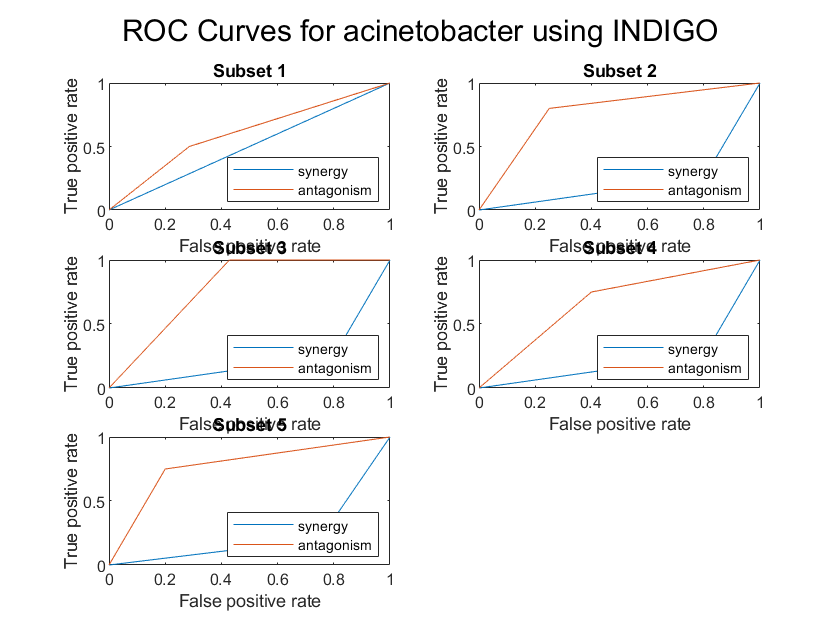

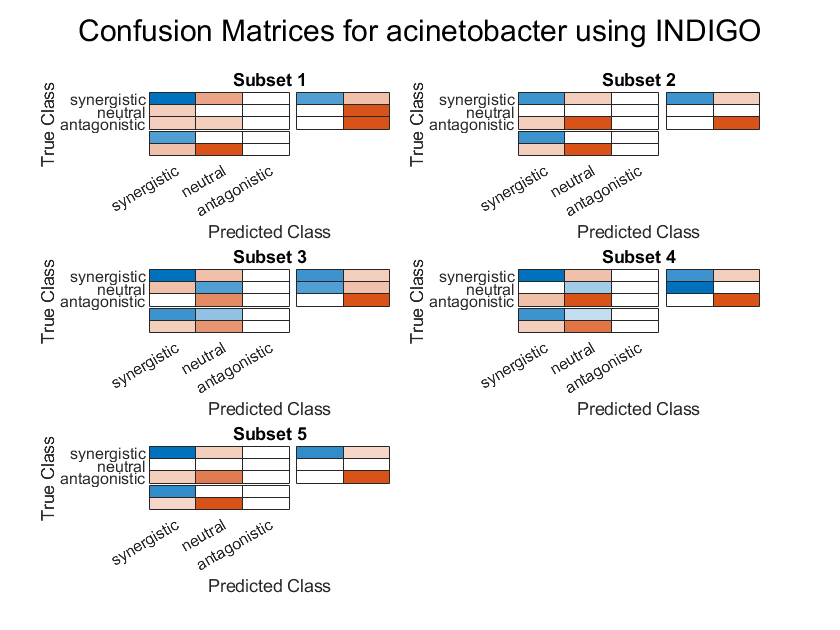

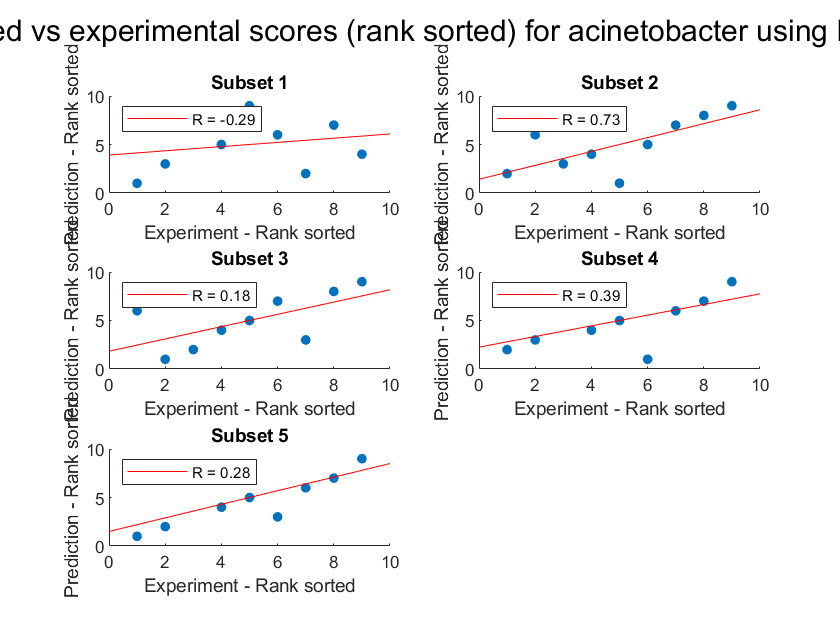

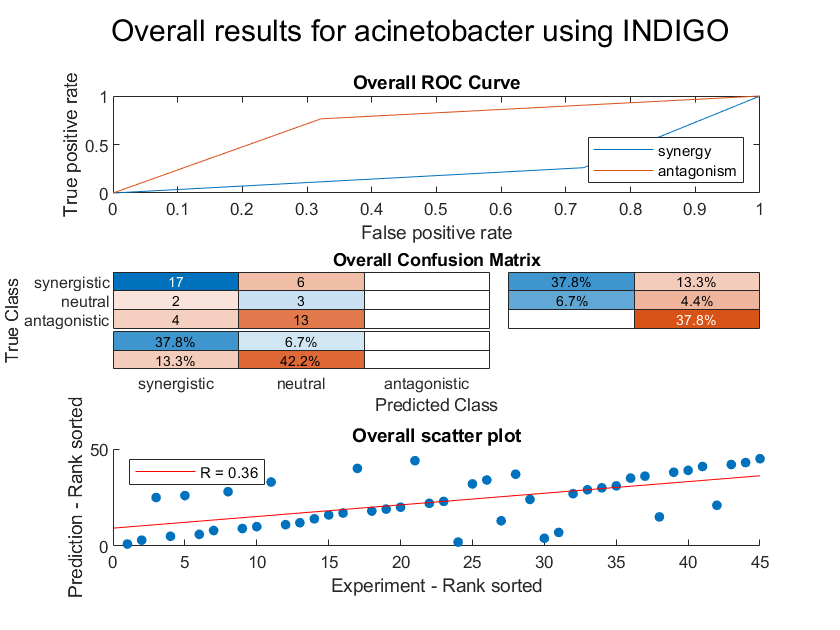

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          -0.28694    

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.25921
    P value                     0.37679
    Accuracy                    0.44444
    Absolute error              0.64444
    Precision (synergy)         0.74333
    Recall (synergy)            0.74333
    Precision (antagonism)          NaN
    Recall (antagonism)               0
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)            0.28
    AUC - ROC (antagonism)      0.72357


overviewTable = 12×1 table
                                 Value  
                                ________

    Interactions                      45
    R (rank)                     0.35693
    P value                     0.016092
    Accuracy                     0.44444
    Absolute error               0.64444
    Precision (synergy)          0.73913
    Recall (synergy)             0.73913
    Precision (antagonism)           NaN
    Recall (antagonism)                0
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)           0.2668
    AUC - ROC (antagonism)       0.72164


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'acinetobacter.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'
                'stlt2.xlsx'
                'st14028.xlsx'
                'pao1.xlsx'
                'pa14.xlsx'};
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 170.652936 seconds.
Run 2
Elapsed time is 206.883545 seconds.
Run 3
Elapsed time is 197.539580 seconds.
Run 4
Elapsed time is 254.698477 seconds.
Run 5
Elapsed time is 376.444813 seconds.


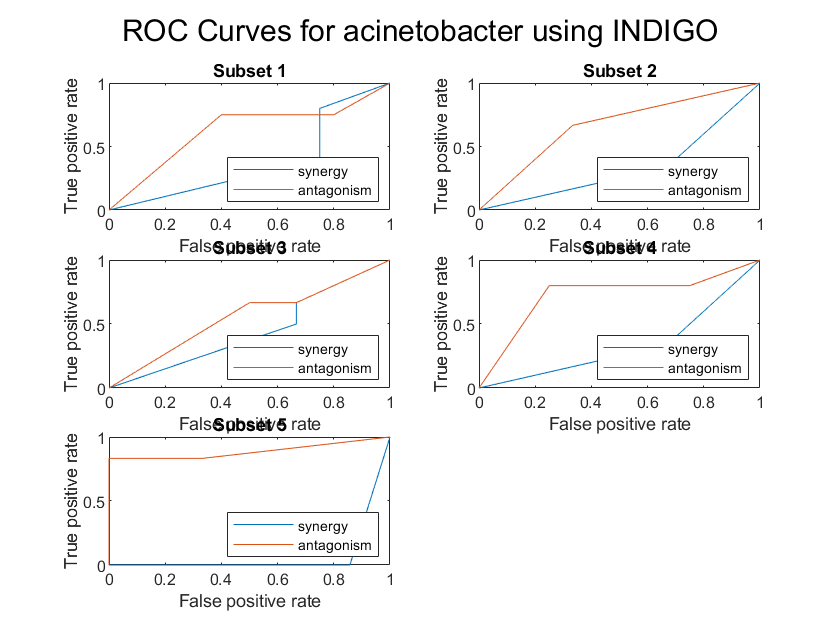

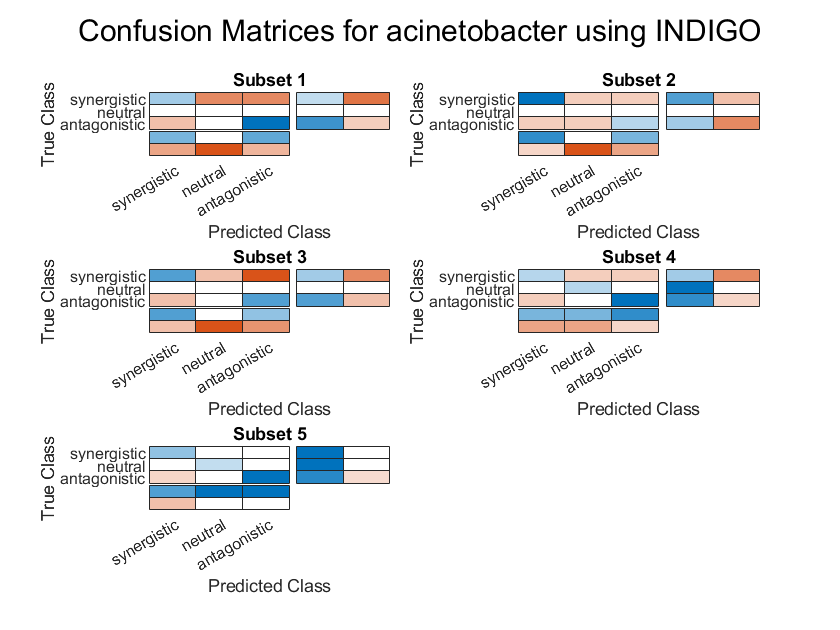

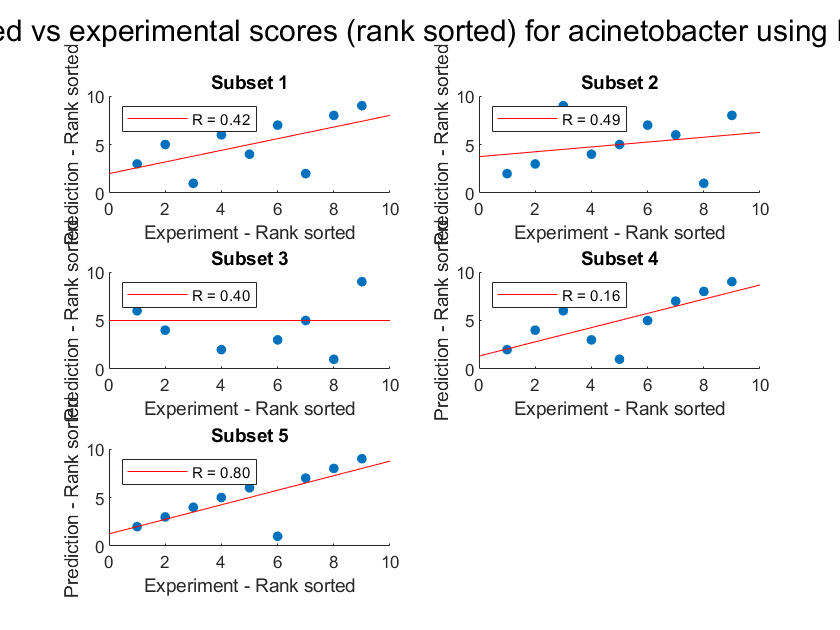

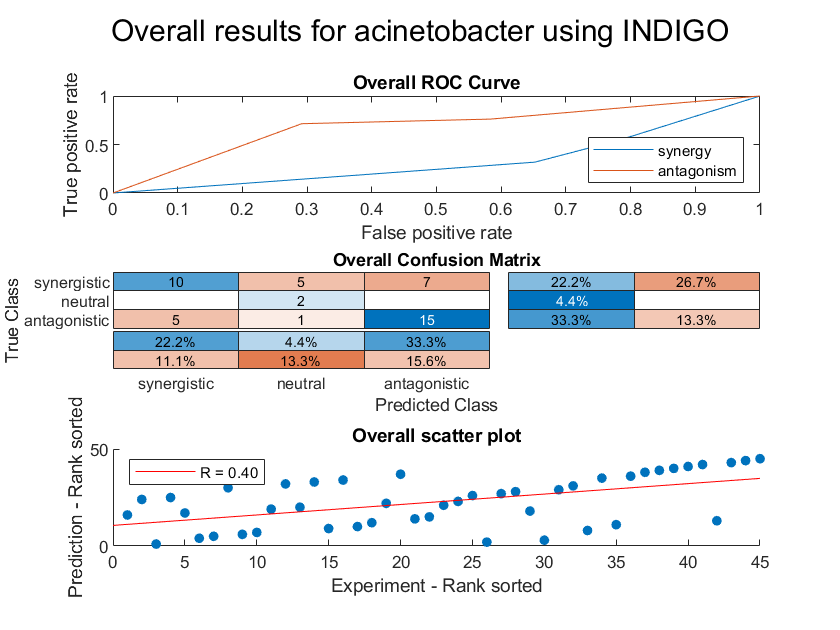

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          0.41667     

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.45221
    P value                     0.28713
    Accuracy                        0.6
    Absolute error              0.66667
    Precision (synergy)         0.62667
    Recall (synergy)            0.50667
    Precision (antagonism)         0.66
    Recall (antagonism)         0.67667
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.31151
    AUC - ROC (antagonism)      0.69222


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       45
    R (rank)                      0.39687
    P value                     0.0069497
    Accuracy                          0.6
    Absolute error                0.66667
    Precision (synergy)           0.66667
    Recall (synergy)              0.45455
    Precision (antagonism)        0.68182
    Recall (antagonism)           0.71429
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.32806
    AUC - ROC (antagonism)        0.68651


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'acinetobacter.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'};
valMethod = 'cv';
K = 5;
standardize = '';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 57.583380 seconds.
Run 2
Elapsed time is 58.250654 seconds.
Run 3
Elapsed time is 63.924305 seconds.
Run 4
Elapsed time is 60.774487 seconds.
Run 5
Elapsed time is 67.048796 seconds.


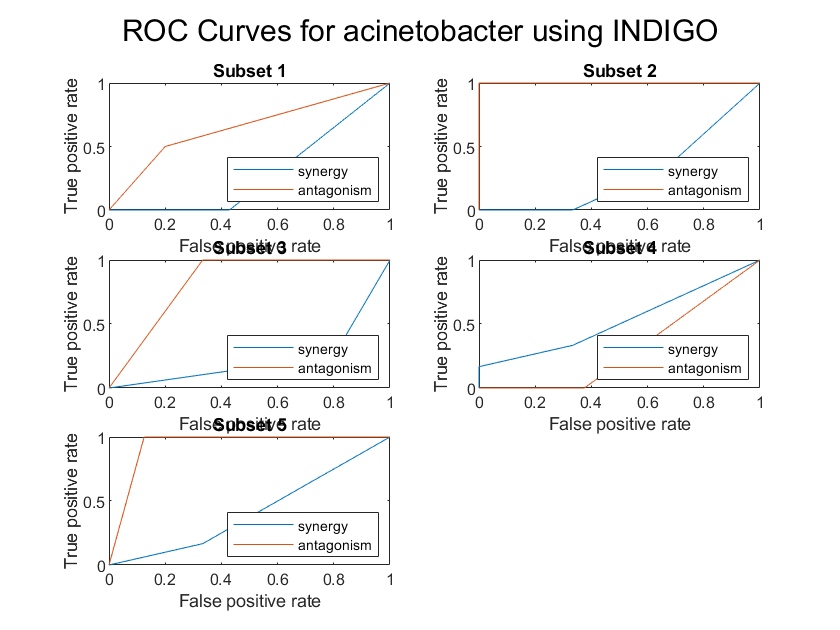

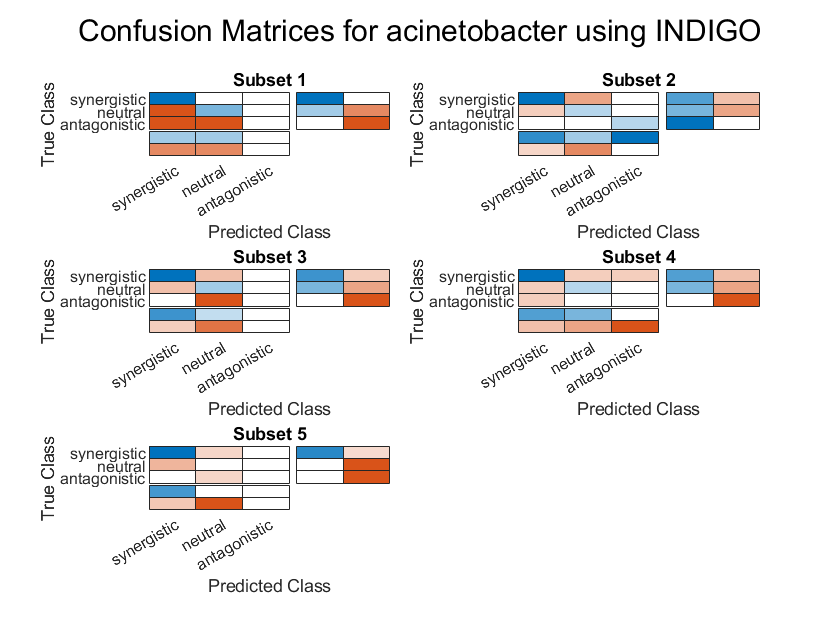

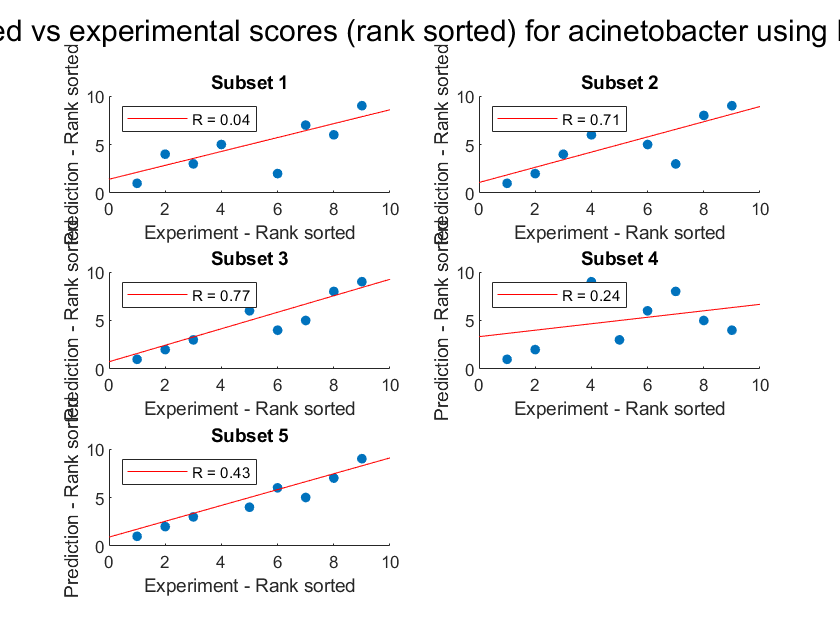

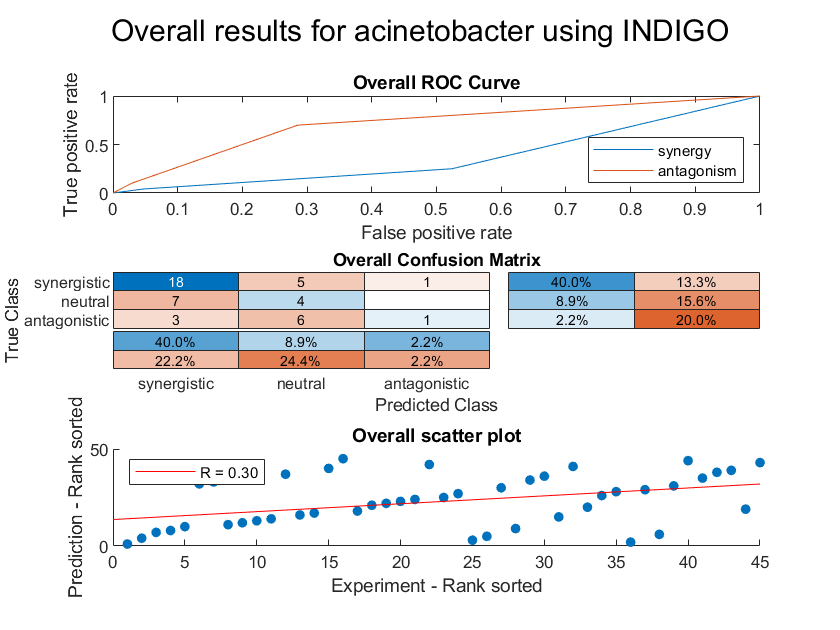

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9          0.041841    

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                    0.44143
    P value                       0.349
    Accuracy                    0.51111
    Absolute error              0.57778
    Precision (synergy)         0.65286
    Recall (synergy)            0.78333
    Precision (antagonism)          NaN
    Recall (antagonism)             0.2
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.34659
    AUC - ROC (antagonism)      0.74667


overviewTable = 12×1 table
                                 Value 
                                _______

    Interactions                     45
    R (rank)                    0.29523
    P value                     0.04897
    Accuracy                    0.51111
    Absolute error              0.57778
    Precision (synergy)         0.64286
    Recall (synergy)               0.75
    Precision (antagonism)          0.5
    Recall (antagonism)             0.1
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.36806
    AUC - ROC (antagonism)      0.71143


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'acinetobacter.xlsx';
trainingData = {'ecoli_bw25113.xlsx'
                'ecoli_iAi1.xlsx'};
valMethod = 'cv';
K = 5;
standardize = 'standardized';
input_type = 2;

indigoSummary = indigoRun(testFile,trainingData,valMethod,K,standardize,input_type);

Run 1
Elapsed time is 58.832833 seconds.
Run 2
Elapsed time is 57.649869 seconds.
Run 3
Elapsed time is 62.912911 seconds.
Run 4
Elapsed time is 65.114205 seconds.
Run 5
Elapsed time is 78.683282 seconds.


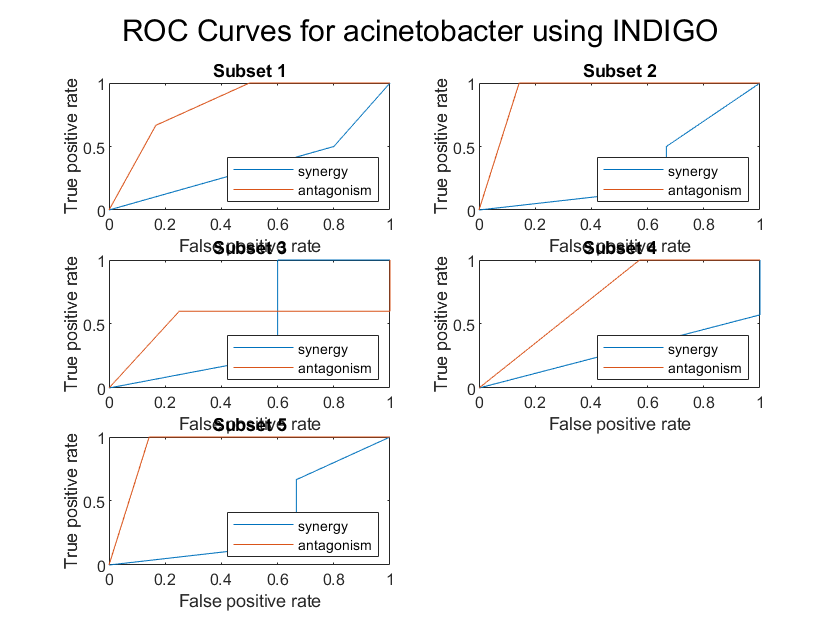

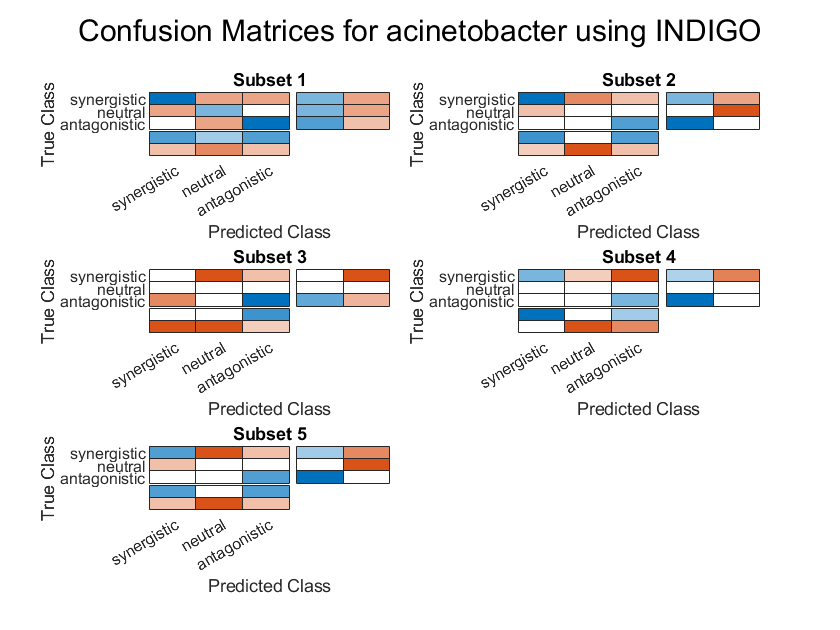

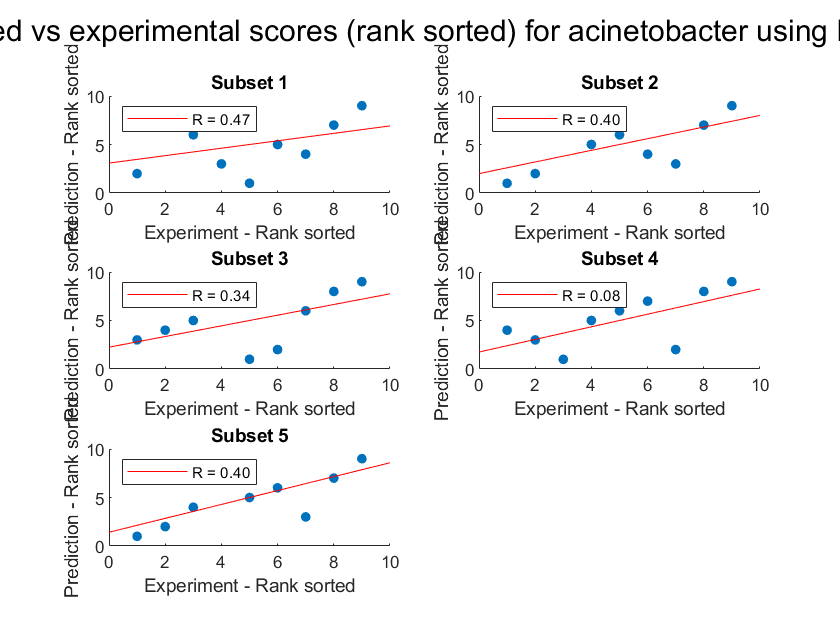

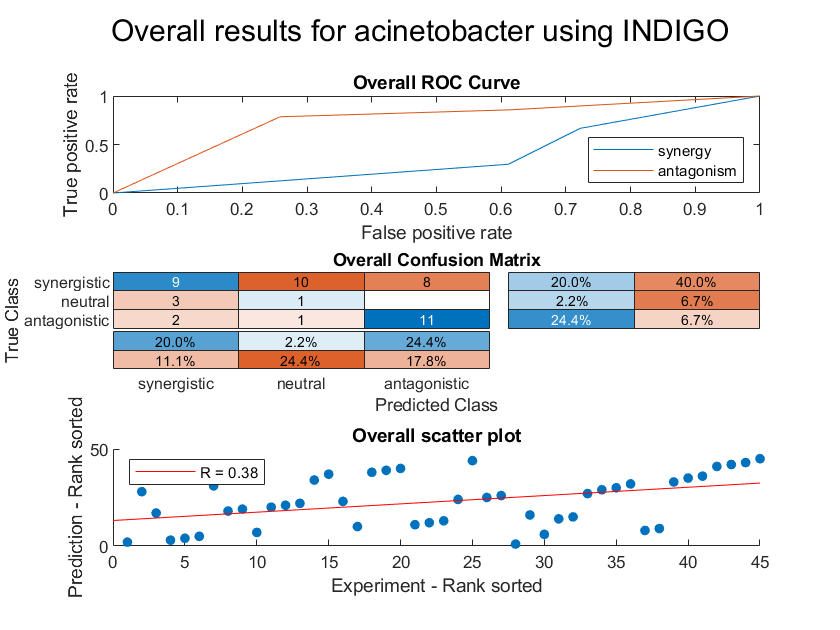

resultsTable = 5×12 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         9           0.46667    0.

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                      9
    R (rank)                     0.3363
    P value                     0.40134
    Accuracy                    0.46667
    Absolute error              0.75556
    Precision (synergy)         0.61667
    Recall (synergy)            0.32381
    Precision (antagonism)      0.61667
    Recall (antagonism)         0.85333
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.34992
    AUC - ROC (antagonism)      0.78595


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       45
    R (rank)                      0.38229
    P value                     0.0095547
    Accuracy                      0.46667
    Absolute error                0.75556
    Precision (synergy)           0.64286
    Recall (synergy)              0.33333
    Precision (antagonism)        0.57895
    Recall (antagonism)           0.78571
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.37551
    AUC - ROC (antagonism)         0.7523


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))